# Segundo Examen Parcial

# Primavera 2024

Sube tu archivo resultado a Canvas $\to$ Examen Parcial 2 antes de las 11:30 horas. 

Cada pregunta vale 5 puntos.

**Aseguráte de que tus resultados se despliegan en el archivo que subas.**

**Las funciones que utilices deben estar al final del script y no deben estar comentadas.**

Los exámenes son trabajos individuales. Está estrictamente prohibido dar o recibir ayuda de cualquier persona. 

Recuerda salvar frecuentemente tu archivo.

Puede ser conveniente limpiar periódicamente el espacio de trabajo (comando clear).

## 1. Sistemas tridiagonales de ecuaciones lineales

Resuelve de la manera más ***eficiente*** posible los siguientes sistemas $A\;x=b\;$, donde

a) $A$ es una matriz triangular inferior. Nota que la matriz no tiene diagonal unitaria.


$$\left\lbrack \begin{array}{ccc}
3 & 0 & 0\\
-1 & 2 & 0\\
-4 & 1 & 4
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3\\
-5\\
9
\end{array}\right\rbrack$$


ATI = [3,0,0; -1,2,0; -4,1,4];
b = [-3;-5;9];
x = forwardSubstitution(ATI, b);
x

x =     -1
    -3
     2


b) $A$ es una matriz triangular superior. 


$$\left\lbrack \begin{array}{cccc}
2 & -1 & 3 & -3\\
0 & -1 & 5 & 2\\
0 & 0 & 4 & 1\\
0 & 0 & 0 & -3
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
-9\\
-3\\
9
\end{array}\right\rbrack$$


ATS = [2,-1,3,-3; 0,-1,5,2; 0,0,4,1; 0,0,0,-3];
b = [2;-9;-3;9];
x = backwardSubstitution(ATS, b);
x

x =    14.5000
   12.0000
   -3.0000
   -3.0000


## 2. Matrices siméticas positivas definidas 

Considera la siguiente matriz$A$:


$$\left\lbrack \begin{array}{ccc}
1 & -1 & 1\\
-1 & 5 & -5\\
1 & -5 & 6
\end{array}\right\rbrack$$


a) Usando funciones de MATLAB, muestra en una línea que $A$ es es simétrica y positiva definida (***todos*** sus eigenvalores son positivos).

A = [1,-1,1; -1,5,-5; 1,-5,6];
all(eig(A) > 0)

ans = logical
   1


b) Escribe la función *cholesky* al final del script. La función debe utilizar solo un ciclo.

c) Utiliza tu función *cholesky *para encontrar la factorización $A=L{*L}^{\prime }$. Comprueba tu resultado.

L = cholesky(A);

d) Utilizando L, calcula el determinante de $A$.

d = 2*prod(diag(L));
d

d = 4

e) Utilizando L y L', calcula la inversa de $A$.

invA = backslashSubstitution(L, L', eye(size(A)));
invA

invA =     1.2500    0.2500         0
    0.2500    1.2500    1.0000
         0    1.0000    1.0000


## 3. Sistema de ecuaciones no lineales.

Encuentra ***tres*** soluciones diferentes del siguiente sistema de ecuaciones no lineales:

 
$$f_1 \left(x,y\right)=x^2 -x+y-0\ldotp 75=0$$



$$f_2 \left(x,y\right)=x^2 -5xy-y=0$$


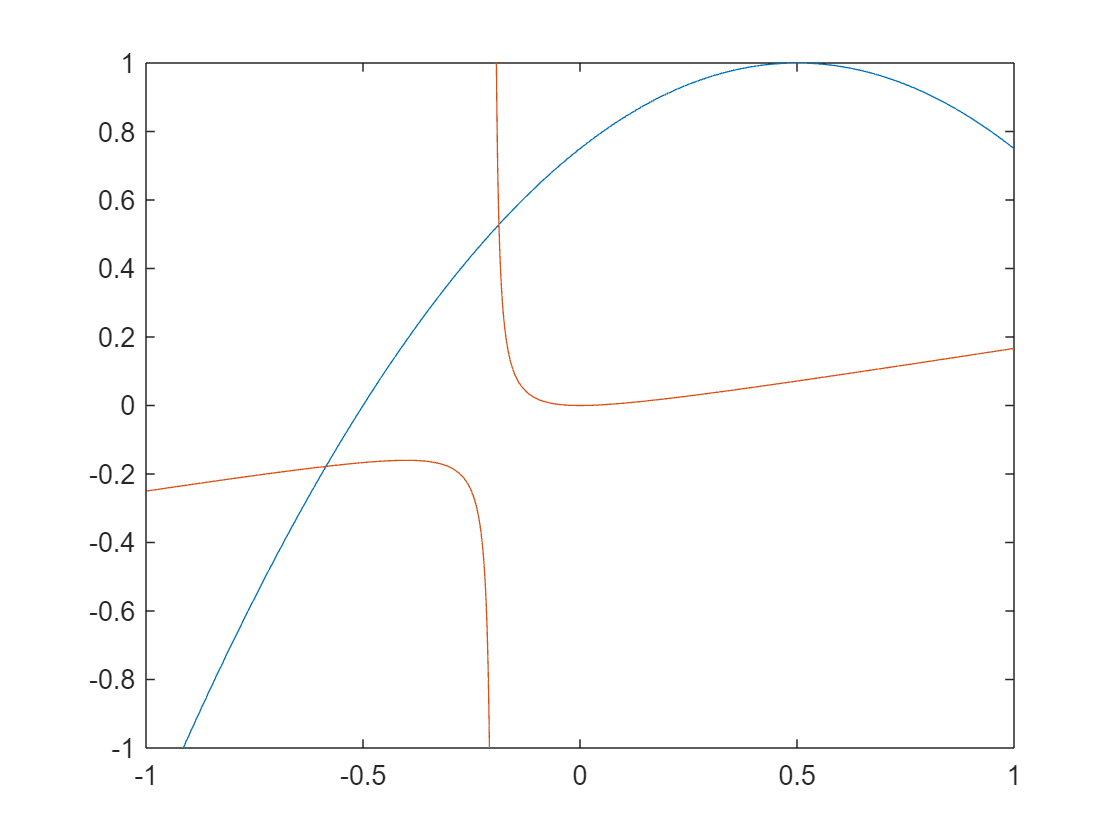

f1 = @(x1, x2) x1.^2 - x1 + x2 - 0.75;
f2 = @(x1, x2) x1.^2 - 5.*x1.*x2 - x2;
fimplicit(f1, [-1 1])
hold on
fimplicit(f2, [-1 1])
hold off


f = @(x) [x(1).^2 - x(1) + x(2) - 0.75; x(1).^2 - 5.*x(1).*x(2) - x(2)];
x0 = [-1; -0.5];
x1 = [-0.2; 0];
x2 = [1; 1.5];
[x, i] = newtonRaphsonMult(f, x0);
fprintf('El resutado es: %f, %f en %d iteraciones', x(1), x(2), i)

El resutado es: -0.585274, -0.177819 en 5 iteraciones

[x, i] = newtonRaphsonMult(f, x1);
fprintf('El resutado es: %f, %f en %d iteraciones', x(1), x(2), i)

El resutado es: -0.186792, 0.528317 en 5 iteraciones

[x, i] = newtonRaphsonMult(f, x2);
fprintf('El resutado es: %f, %f en %d iteraciones', x(1), x(2), i)

El resutado es: 1.372065, 0.239502 en 9 iteraciones

## 4. Algoritmos iterativos: Jacobi y Gauss-Seidel. 

Considera la siguiente matriz $A$:


$$\left\lbrack \begin{array}{cccc}
-2 & 1 & 0 & 0\\
1 & -2 & 1 & 0\\
0 & 1 & -2 & 1\\
0 & 0 & 1 & -2
\end{array}\right\rbrack$$


A = [-2,1,0,0;1,-2,1,0;0,1,-2,1;0,0,1,-2];

a) ¿Es diagonal estrictamente dominante?

dd = strictDominantDiagonal(A);
if dd, fprintf('Si');
else, fprintf('No'); end

No

b) ¿Las matrices de transición $T$ para Jacobi y Gauss-Seidel tienen radio espectral menor a 1?

Si $\lambda_i$, ..., $\lambda_i$ son los valores propios de una matriz *A*, entonces su radio espectral se define como: 

$\rho \left(A\right)=\max \left(\left|\lambda_i \right|\right)$max

Recuerda que las matrices de transición son:

Gauss-Seidel $T=-{\left(L+D\right)}^{-1} U$

Jacobi $T=-D^{-1} \left(L+U\right)$

[L, U] = lup(A);
D = diag(diag(A));
[m, n] = size(A)

m = 4

n = 4

I = eye(m, n);

% Gauss Seidel
invLD = forwardSubstitutionMat(L+D, I);
Tgs = -invLD*U;
[~, eigTgs] = powerMethod(Tgs);
eigTgs < 1

ans = logical
   1



% Jacobi
invD = I/D;
Tjb = invD*(L+U);
[~, eigTjb] = powerMethod(Tjb);
eigTjb < 1

ans = logical
   1


c) Resuelve el sistema usando Gauss-Seidel, si 


$$b=\left\lbrack \begin{array}{c}
-1\\
0\\
0\\
0
\end{array}\right\rbrack$$


b = [-1; 0; 0; 0];
x = gaussSeidel(A, b);

x

x =     0.8000
    0.6000
    0.4000
    0.2000


## 5. Formato comprimido por columna.

Resuelve el problema anterior usando el método de Jacobi y la representación comprimida de $A$.

A;
b;
x = [-2,1, 1,-2,1, 1,-2,1, 1,-2];
i = [1,2, 1,2,3, 2,3,4, 3,4];
p = [1,3,6,9,11];

X = jacobi(A, b);

X

X =     0.5000
         0
         0
         0


a) Encuentra las dimensiones de $A$ y el número de elementos diferentes de cero (*nzz*).

[m, idx] = max(i);


dims = [m m];
dims

dims =      4     4


difDeCero = length(x);
difDeCero

difDeCero = 10

b) Obten de $x$ los elementos de la diagonal de $A$. Supón que $A$ es invertible y que no tiene ceros en la diagonal.

d = zeros(1, n);
j = 1;
k = 1;
while j < n
    if k == j
        d(j)= x(k);
        j = j+1;
    end
    k = k+1;
end
d

d =     -2     1     1     0


c) Resuelve el sistema de ecuaciones con la fórmula

$x_{i+1} =x_i +D^{-1} r$, donde $r=Ax_i -b$

Recuerda que $Ax_i$ puede expresarse como una combinación lineal de las columnas de $A$:


$$A*x_i =\sum_{j=1}^n x_i \left(j\right)*A\left(:,j\right)$$
 

x = formula(A, b);
x

x =     -8
     0
     0
     0


function [x, i] = formula(A, b)
    rTol = 0.5e-5;
    itMax = 150;
    [m, n] = size(A);
    invD = diag(diag(A))/eye(m, n);

    x = zeros(m, 1);
    i = 0;
    condicion = true;
    while condicion
        xp = x;
        
        r = xp(1)*A(:,1) - b;
        for j = 2:n
            r = r + xp(j)*A(:,j) - b;
        end
        for j = 1:n
            x = xp + invD*r;
        end
        
        i = i + 1;
        condicion = norm((x-xp)./x, Inf) > rTol && i < itMax;
    end
end

## Métodos utilizados

function x = forwardSubstitution(L, b)
    [m,n] = size(L);
    if m~=n, error('Matrix A must be square'), end
    if m~=length(b), error('Wrong dimension on b'), end
    
    x = zeros(size(b));
    x(1) = b(1)/L(1,1);
    for i = 2:n
        x(i) = (b(i) - L(i, 1:i-1)*x(1:i-1))/L(i, i);
    end
end

function x = backwardSubstitution(U, b)
    [m,n] = size(U);
    if m~=n, error('Matrix A must be square'), end
    if m~=length(b), error('Wrong dimension on b'), end
    
    x = zeros(size(b));
    x(n) = b(n)/U(n,n);
    for i = n-1:-1:1
        x(i) = (b(i)- U(i, i+1:end)*b(i+1:end))/U(i,i);
    end
end

function X = forwardSubstitutionMat(L, B)
    [m, n] = size(B);

    X = zeros(m, n);
    X(1, :) = B(1, :)/L(1, 1);
    for i = 2:m
        X(i, :) = (B(i, :) - L(i, 1:i-1)*X(1:i-1, :))/L(i, i);
    end
end

function X = backslashSubstitution(L, U, B)
    [m, n] = size(B);

    Y = zeros(m, n);
    Y(1, :) = B(1, :)/L(1, 1);
    for i = 2:m
        Y(i, :) = (B(i, :) - L(i, 1:i-1)*Y(1:i-1, :))/L(i, i);
    end

    X = zeros(m, n);
    X(m, :) = Y(m, :)/U(m, m);
    for i = m-1:-1:1
        X(i, :) = (Y(i, :) - U(i, i+1:end)*X(i+1:end, :))/U(i, i);
    end
end

function L = cholesky(A)
    if ~issymmetric(A), error('Matrix must be symmetric'); end
    n = length(A);

    L = zeros(n, n);
    L(1, 1) = sqrt(A(1, 1));
    L(:, 1) = A(:, 1)/L(1, 1);

    for i = 2:n-1
        L(i, i) = sqrt(A(i, i) - L(i, 1:i-1).^2);
    end
    
    for j = 2:n
        for i = j+1:n
            L(i, j) = (A(i, j) - L(i, 1:j-1)*L(j, 1:j-1)')/L(j, j);
        end
    end

    L(n, n) = sqrt(A(n, n) - sum(L(n, 1:n-1).^2));
    
    if ~(isreal(diag(L))), error('Matrix is not positive definite'); end
end

function pd = strictDominantDiagonal(A)
    [m, n] = size(A);
    if m ~= n, error('Matrix is not square'); end

    pd = abs(A(1, 1)) > abs(sum(A(1, 2:end)));
    i = 2;
    while i < n && pd
        pd = sum(abs([A(i, i+1:n) A(i, 1:i-1)])) < abs(A(i, i));
        
        i = i+1;
    end
end

function [x, i] = gaussSeidel(A, b, x0, rTol, itMax)
    if ~strictDominantDiagonal(A), warning('Matrix doesnt have a strict dominant diagonal'); end
    n = length(A);

    if ~exist("rTol", "var"), rTol = 0.5e-5; end
    if ~exist("itMax", "var"), itMax = 100; end
    if ~exist("x0","var"), x0 = zeros(size(b)); end

    x = x0;
    i = 0;
    condition = true;
    while condition
        xp = x;
        x(1) = (b(1) - A(1, 2:n)*x(2:n))/A(1, 1);
        for j = 2:n-1
            x(j) = (b(j) - A(j, 1:j-1)*x(1:j-1) - A(j, j+1:n)*x(j+1:n))/A(j, j);
        end
        x(n) = (b(n) - A(n, 1:n-1)*x(1:n-1))/A(n, n);
        i = i + 1;
        condition = norm((x-xp)./x, Inf) > rTol && i < itMax;
    end
end

function [x, i] = jacobi(A, b, x0, rTol, itMax)
    if ~strictDominantDiagonal(A), warning('The matrix does not have a strict dominant diagonal'); end
    [n, m] = size(b);

    if ~exist("x0", "var"), x0 = zeros([n m]); end
    if ~exist("rTol", "var"), rTol = 0.5e-5; end
    if ~exist("itMax", "var"), itMax = 100; end
    
    x = x0;
    i = 1;
    condition = true;
    while condition
        xp = x;
        x(1) = (b(1) - A(1, 2:n)*xp(2:n))/A(1, 1);

        for j = 2:n-1
            x(j) = (b(j) - A(j, 1:j-1)*xp(1:j-1) - A(j, j+1:n)*xp(j+1:n))/A(j, j);
        end
        x(n) = (b(n) - A(n, 1:n-1)*xp(1:n-1))/A(n, n);
        
        i = i + 1;
        condition = norm((x-xp)./x, Inf) > rTol && i < itMax;
    end
end

function [L, U, p, s] = lup(A)
    [m,n] = size(A);
    if m~=n, error('Matrix A must be square'), end

    U = A;
    L = eye(n);
    p = 1:n;
    s = 1;
    
    for j = 1 : n-1
        [~, r] = max(abs(U(j:n, j)));
        mayorI = j + r - 1;

        if mayorI ~= j 
            L([j, mayorI], 1:j-1) = L([mayorI, j], 1:j-1);
            U([j, mayorI], j:n) = U([mayorI, j], j:n);
            p([j, mayorI]) = p([mayorI, j]);
            s = -s;
        end

        for i = j+1:n
            mult = U(i, j)/U(j, j);
            U(i, j+1:n) = U(i, j+1:n) - mult*U(j, j+1:n);
            U(i, 1:j) = 0;
            L(i, j) = mult;
        end
    end
end

function [x, lambda] = powerMethod(A, itMax, rTol)
    [m, n] = size(A);
    if m ~= n, error('Matrix is not square'), end

    if ~exist('itMax', 'var'), itMax = 150; end
    if ~exist('rTol', 'var'), rTol = 0.5e-5; end

    x = rand([m 1]);
    x = x/norm(x, 2);

    i = 0;
    condition = true;
    while condition
        xp = x;
        ax = A*x;
        x = (ax)/norm(ax);
        
        e = norm(x-xp./x, Inf);
        i = i+1;
        condition = e > rTol && i < itMax;
    end
    lambda = dot(x, A*x)/dot(x, x);
end

function [x, i] = newtonRaphsonMult(f, x0, rTol, itMax)
    if ~exist('rTol', 'var'), rTol = 0.5e-5; end
    if ~exist('itMax', 'var'), itMax = 150; end

    x = x0;
    i = 0;
    condition = true;
    while condition
        xp = x;
        x = xp - jacobianNR(f, xp)\f(xp);

        i = i + 1;
        condition = norm((x-xp)./x, Inf) > rTol && i < itMax;
    end

    if i == itMax
        warning('newtonRaphsonMult:IterationLimitReached', 'The iteration limit was reached')
    end
end

function J = jacobianNR(f, x, h)
    if ~exist('h', 'var'), h = 1e-6; end

    n = length(x);

    J = zeros(n, n);
    Dx = h*eye(n);
    for i = 1:n
        J(:, i) = (f(x + Dx(:, i)) - f(x - Dx(:, i)))/(2*h);
    end
end